# **Analysis 1: Live cell analysis**

**Testing for:**

**YFP1: chromatin-bound MCM2**

**FarRed1: chromatin-bound PCNA**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
%     'DMSO',2,2,1:9,[0 0 0]; %1
         'DMSO',2:4,2:6,1:9,[0 0 0]; %1
         'DOX',2:4,7:11,1:9,[0 0 0]; %1

    };



load([dataDir filesep 'C219_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/3;
frameDrugAdded = 0;                                                  
frameEdU = 0;
folding = 0;

rawdir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C219_Images\';
impath = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C219_Images\';
formatCode = 'Time%1$05d_Well%2$s_Point%2$s_%3$04d_*.tiff';

numFrames = size(S(1).area,2);
xFrames = 1:numFrames; 
xTime = (xFrames-1)./framesPerHr;

map = nikon_well_offset_new(conditions,9,1);
POI_time = arrayfun(@(x) (numFrames - x.POI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/framesPerHr, S,'UniformOutput',false);
[S.POI_time] = POI_time{:};

**Set Thresholds**

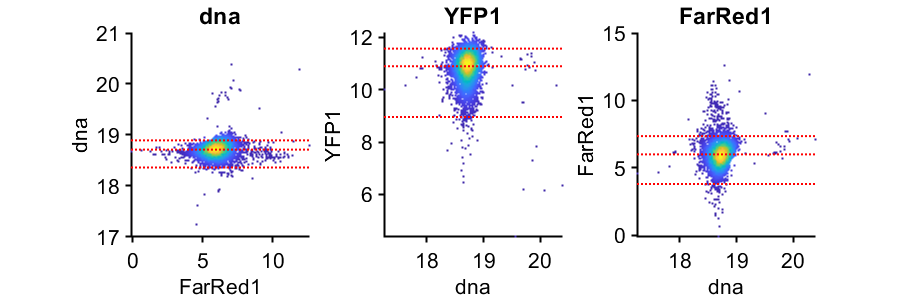

%% set G1 phase gates
cond=1;
gates = {'dna','YFP1','FarRed1'};
plotting = {'FarRed1','dna','dna'};
prctiles = {[1 50 95],[1 50 95],[1 50 95]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) > .5 & S(cond).POI_time(:,1) < 1  ;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

conds=[1 2 2 2 2 1];
rng(1)
test = {};
ally = [];
group = [];
for i = 1:length(conds)
    condition = conds(i);
    ydata = real(log2(S(condition).YFP1));
    
    if ismember(i,[1])
        %early S DMSO
        inds = S(condition).POI(:,1) <= 1 * framesPerHr & (S(condition).POI_time(:,3)) <=1;
    elseif ismember(i,[2 3])
        %early S DMSO
        inds = S(condition).POI(:,1) <= 1 * framesPerHr & (S(condition).POI_time(:,3)) <=1;
    elseif ismember(i,[4 5])
        % inhibited G1 DOX
        inds = S(condition).POI_time(:,1) <= 1 & S(condition).POI_time(:,1) >=.5;
    elseif ismember(i,[6])
        %G2
         inds = S(condition).allDNA > 2^19.6 & S(condition).allFarRed1 < 2^8;
        ydata = real(log2(S(condition).allYFP1));
    end
    
    ydata = ydata(inds);
    if ismember(i,[3 5])
        ydata = ydata(ydata < prctile(ydata,50));
        
    end
    
    ydata = randsample(ydata,min([length(ydata), 1000]));
    %     ydata(ydata<1) = 1;
    test{i} = ydata;
    ally = [ally; ydata];
    group = [group; repmat(i,size(ydata))];
    meds(i) = median(ydata);
    
end
meds

meds =    11.6595   10.9632   10.3059    6.2429    4.9897    5.5219


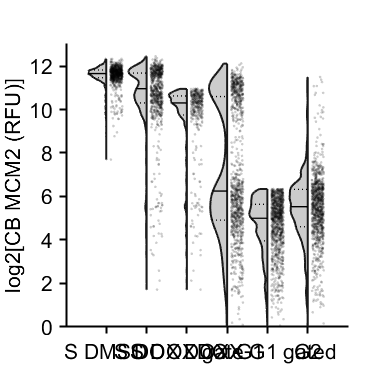

figure;

% [h,p,ci,stats] = ttest2((test{1}),(test{2}))
% notBoxPlot((ally),group)


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'S DMSO','S DOX','S DOX gate','DOX G1 ','DOX G1 gated','G2'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,'k','filled','MarkerFaceAlpha',.2);
ylabel('log2[CB MCM2 (RFU)]')
set(gca,'FontSize',16)
ylim([ 0 13 ])
% hline(2^7.5)
% xtickangle(45)
axis square
print_pdf([pwd() '\Figs\mcm2_compare_scatter_extra.pdf'])

**Time since CRL PCNA levels for export**

rng(1)
cond=1;
poiAligned=3;
offset=0;


rng(1)
gateVals = {{'FarRed1'},{},{},{}};
rangeVals = {{[2^3 Inf]},{[0 2^4.5]},{},{}};
edges = (0/framesPerHr:(1/framesPerHr):17);


ind= ~isnan(S(cond).POI_time(:,poiAligned(1))) & ...
    gate_vals(S(cond), gateVals{1}, rangeVals{1}) &  S(cond).POI_time(:,poiAligned) <=3;

xdata = S(cond).POI_time(ind,poiAligned);
ydata = [];
ydata(:, 1) = log2(S(cond).FarRed1(ind)) ;

ind = downsample_bins(xdata, edges);
xdata = xdata(ind);
ydata = ydata(ind,:);


[binData, edges] = bin_xy(xdata, ydata, {'mean','median'},...
    'Edges',edges);
midpoints = (edges(1:end-1) + edges(2:end))/2;
% midpoints = midpoints(1:end-1);

f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
hold on
subs_cells = randsample(size(ydata,1),1000);
subs = false(size(ydata,1),1);
subs(subs_cells) = true;

false_pos = sum(2.^ydata<gate.FarRed1_G1(3))/length(ydata)

false_pos = 0.0251

length(ydata)

ans = 10113

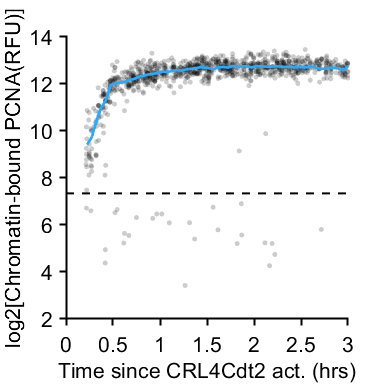


scatter(xdata(subs),ydata(subs,1),15,'k','filled','MarkerFaceAlpha',.2)
plot(midpoints,binData(1).median,'Color',[39 170 255]/255,'LineWidth',2);
% ylim([2 13]);
xlim([0 3]);
xticks([0:.5:3])
ylabel('log2[Chromatin-bound PCNA(RFU)]');xlabel({'Time since CRL4Cdt2 act. (hrs)'});
%title(conditions{conds(i),1});
h=hline(log2(gate.FarRed1_G1(3)),'k--');
axis square
hold off
print_pdf([pwd() '\Figs\PCNA_timesinceSlog_noG1.pdf'])

**look at traces**

Gate for early mitosis, first .3 hrs, high/low geminin

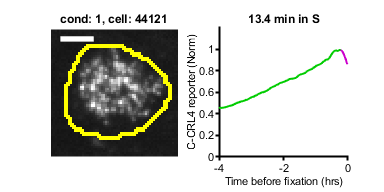

cond=[1];
poi_align = 4;
sizeBox = 30;
max_cells = 10;
rng(10)
range1 = [0 3000];


pixel_size = .625; %um/pixel
bar_length = 10/pixel_size;
exclude = {[],[]};
g1col = [0 .8 0];
scol = [.8 0 .8];
smooth_size = 7;
postbuff = 4;
filtPoints = floor((smooth_size - 1)/2);

ind = S(cond).POI_time(:,poi_align) >= 0/60 & S(cond).POI_time(:,poi_align) <= 15/60 & S(cond).POI_time(:,1) > 4;
cells = find(ind);
cells = cells(~ismember(cells,exclude{cond}));
num_cells = min([max_cells length(cells)]);
rsamp = randsample(length(cells),num_cells);
cells = cells(rsamp);
cells = [44121];

for i = 1:length(cells)
    c = cells(i);
    %crlNuc = nansmoothm(dat(cond).crlNormAct(c,:),5,'sgolay');
    crlNuc = smoothdata(S(cond).crlNormAct(c,:),2, 'sgolay',[filtPoints min([postbuff, filtPoints ])], 'omitnan','degree',3);
    offset = max(xTime) + (S(cond).POI_time(c,poi_align) - (numFrames - S(cond).POI(c,poi_align))/framesPerHr) ;
    
    shot = [num2str(S(cond).fixedRow(c)),'_',num2str(S(cond).fixedCol(c)),'_',num2str(S(cond).fixedSite(c))];
    row = S(cond).fixedRow(c);
    col = S(cond).fixedCol(c);
    site = S(cond).fixedSite(c);
    x = (S(cond).x(c))/.5;
    y = (S(cond).y(c))/.5;
    pois = S(cond).POI(c,:);
    

    shotSearch = sprintf(formatCode,0,rowColumnTowellName(row,col),site-1);
    fileName = findFile(rawdir,shotSearch);

%     move_folder = fullfile(dataDir,'C219_Images',shot,filesep);
%     mkdir(move_folder)
%     
%     copyfile([impath shot '\' shot '_mask.tif'],[move_folder '\' shot '_mask.tif'])
%     copyfile(fullfile(rawdir,fileName),fullfile(move_folder))
    im_mask=imresize(imread([impath shot '\' shot '_mask.tif']),2);
    im1=imread(fullfile(rawdir,fileName),3);
    
    
    mask_fill = imfill(im_mask,'holes');
    im_mask = imdilate(mask_fill,strel('disk',1)) - imerode(mask_fill,strel('disk',1));
    mask_label = bwlabel(mask_fill);
    cell_label = mask_label(round(y),round(x));
    cell_mask = mask_label == cell_label;
    cell_bord = imdilate(cell_mask,strel('disk',1)) - imerode(cell_mask,strel('disk',1));
    
    cropx = x + [-sizeBox sizeBox];
    cropx = round(min(max(cropx,0),size(im_mask,1)));
    xmin = cropx(1);
    width = cropx(2) - cropx(1);
    cropy = y + [-sizeBox sizeBox];
    cropy = round(min(max(cropy,0),size(im_mask,2)));
    ymin=cropy(1);
    height = cropy(2) - cropy(1);
    mask_crop= imcrop(im_mask,[xmin ymin width height]);
    im1_crop= imcrop(im1,[xmin ymin width height]);
    cell_crop = imcrop(cell_bord,[xmin ymin width height]);
    
    figure('units','inches','Position',[0 0 2*2 2])
    subplot(1,2,1)
    hold on
    b = mat2gray(im1_crop,range1);
    b = imoverlay(b,mask_crop,'white');
    b = imoverlay(b,cell_crop,'yellow');
    imshow(b);
    plot([5 ,5  +  bar_length], [5, 5 ],'Color','w','LineWidth',4)
    set(gca,'FontSize',8)
    %         t=title({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]},'FontSize',8);
    t=title(sprintf('cond: %d, cell: %d',cond,c),'FontSize',8);
    set(t,'interpreter','none');
    
    subplot(1,2,2)
    hold on
    plot(xTime(1:pois(1)) - offset, crlNuc(1:pois(1)),'Color',[.5 .5 .5]);
    plot(xTime(pois(1):pois(poi_align)) - offset, crlNuc(pois(1):pois(poi_align)),'Color',g1col);
    plot(xTime(pois(poi_align):end) - offset, crlNuc(pois(poi_align):end),'Color',scol);
    
    set(gca,'FontSize',8)
    title(sprintf('%.1f min in S',S(cond).POI_time(c,poi_align)*60),'FontSize',8)
    xlabel('Time before fixation (hrs)','FontSize',8)
    ylabel('C-CRL4 reporter (Norm)','FontSize',8)
    ylim([0 1.2])
    xlim([-4 0])
    axis square
    print_pdf([pwd() '\Figs\cells\images_cond_' num2str(cond) 'cell_' num2str(c) '.pdf'])
    imwrite(b,[pwd() '\Figs\cells\PCNA_small_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
end

**look at traces**

Gate for early mitosis, first .3 hrs, high/low geminin

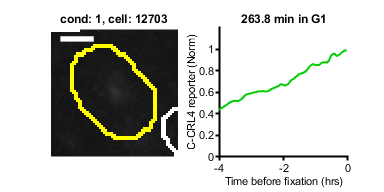

cond=[1];
poi_align = 1;
sizeBox = 30;
max_cells = 10;
rng(10)
range1 = [0 3000];


pixel_size = .625; %um/pixel
bar_length = 10/pixel_size;
exclude = {[],[]};
g1col = [0 .8 0];
scol = [.8 0 .8];
smooth_size = 7;
postbuff = 4;
filtPoints = floor((smooth_size - 1)/2);

ind = S(cond).POI_time(:,1) >4 & S(cond).POI_time(:,1) < 5 & isnan(S(cond).POI_time(:,3));
cells = find(ind);
cells = cells(~ismember(cells,exclude{cond}));
num_cells = min([max_cells length(cells)]);
rsamp = randsample(length(cells),num_cells);
cells = cells(rsamp);
cells = [12703];

for i = 1:length(cells)
    c = cells(i);
    %crlNuc = nansmoothm(dat(cond).crlNormAct(c,:),5,'sgolay');
    crlNuc = smoothdata(S(cond).crlNormAct(c,:),2, 'sgolay',[filtPoints min([postbuff, filtPoints ])], 'omitnan','degree',3);
    offset = max(xTime) + (S(cond).POI_time(c,poi_align) - (numFrames - S(cond).POI(c,poi_align))/framesPerHr) ;
    
    shot = [num2str(S(cond).fixedRow(c)),'_',num2str(S(cond).fixedCol(c)),'_',num2str(S(cond).fixedSite(c))];
    row = S(cond).fixedRow(c);
    col = S(cond).fixedCol(c);
    site = S(cond).fixedSite(c);
    x = (S(cond).x(c))/.5;
    y = (S(cond).y(c))/.5;
    pois = S(cond).POI(c,:);
    
    shotSearch = sprintf(formatCode,0,rowColumnTowellName(row,col),site-1);
    fileName = findFile(rawdir,shotSearch);
    
%         move_folder = fullfile(dataDir,'C219_Images',shot,filesep);
%     mkdir(move_folder)
%     
%     copyfile([impath shot '\' shot '_mask.tif'],[move_folder '\' shot '_mask.tif'])
%     copyfile(fullfile(rawdir,fileName),fullfile(move_folder))
    
    im_mask=imresize(imread([impath shot '\' shot '_mask.tif']),2);
    im1=imread(fullfile(rawdir,fileName),3);
    
    
    mask_fill = imfill(im_mask,'holes');
    im_mask = imdilate(mask_fill,strel('disk',1)) - imerode(mask_fill,strel('disk',1));
    mask_label = bwlabel(mask_fill);
    cell_label = mask_label(round(y),round(x));
    cell_mask = mask_label == cell_label;
    cell_bord = imdilate(cell_mask,strel('disk',1)) - imerode(cell_mask,strel('disk',1));
    
    cropx = x + [-sizeBox sizeBox];
    cropx = round(min(max(cropx,0),size(im_mask,1)));
    xmin = cropx(1);
    width = cropx(2) - cropx(1);
    cropy = y + [-sizeBox sizeBox];
    cropy = round(min(max(cropy,0),size(im_mask,2)));
    ymin=cropy(1);
    height = cropy(2) - cropy(1);
    mask_crop= imcrop(im_mask,[xmin ymin width height]);
    im1_crop= imcrop(im1,[xmin ymin width height]);
    cell_crop = imcrop(cell_bord,[xmin ymin width height]);
    
    figure('units','inches','Position',[0 0 2*2 2])
    subplot(1,2,1)
    hold on
    b = mat2gray(im1_crop,range1);
    b = imoverlay(b,mask_crop,'white');
    b = imoverlay(b,cell_crop,'yellow');
    imshow(b);
    plot([5 ,5  +  bar_length], [5, 5 ],'Color','w','LineWidth',4)
    set(gca,'FontSize',8)
    %         t=title({shot, [' x:' num2str(round(x)) ', y:' num2str(round(y))]},'FontSize',8);
    t=title(sprintf('cond: %d, cell: %d',cond,c),'FontSize',8);
    set(t,'interpreter','none');
    
    subplot(1,2,2)
    hold on
    plot(xTime(1:pois(1)) - offset, crlNuc(1:pois(1)),'Color',[.5 .5 .5]);
    plot(xTime(pois(poi_align):end) - offset, crlNuc(pois(poi_align):end),'Color',g1col);
    
    set(gca,'FontSize',8)
    title(sprintf('%.1f min in G1',S(cond).POI_time(c,poi_align)*60),'FontSize',8)
    xlabel('Time before fixation (hrs)','FontSize',8)
    ylabel('C-CRL4 reporter (Norm)','FontSize',8)
    ylim([0 1.2])
    xlim([-4 0])
    axis square
    print_pdf([pwd() '\Figs\cells\images_cond_' num2str(cond) 'cell_' num2str(c) '.pdf'])
    imwrite(b,[pwd() '\Figs\cells\PCNA_small_images_cond_' num2str(cond) 'cell_' num2str(c) '.tiff'])
end